f=@(x)(x^2)

f = function_handle with value:
    @(x)(x^2)


%f=inline('x^2')
syms x
Vexacto=int(f(x),1,3)

$$Vexacto = \frac{26}{3}$$

Vex=vpa(Vexacto,4) % redoneda a 4 decimales

$$Vex = 8.667$$

a=1; b=3; h=b-a;
Itrap=(h/2)*(f(a)+f(b))

Itrap =     10


Error=vpa(abs(Vex-Itrap),4)

$$Error = 1.333$$

f=@(x)(x^3)

f = function_handle with value:
    @(x)(x^3)


syms x
Vexacto=int(f(x),1,3)

$$Vexacto = 20$$

Vex=vpa(Vexacto,4) % redoneda a 4 decimales

$$Vex = 20.0$$

a=1; b=3; h=(b-a)/2;
Isimp=(h/3)*(f(a)+4*f(a+h)+f(b))

Isimp =     20


Error=vpa(abs(Vex-Isimp),4)

$$Error = 0.0$$

f=@(x)(x^2)

f = function_handle with value:
    @(x)(x^2)


f1=@(x)(x.^2)

f1 = function_handle with value:
    @(x)(x.^2)


syms x
Vexacto=int(f(x),1,3)

$$Vexacto = \frac{26}{3}$$

Vex=vpa(Vexacto,4) % redondea a 4 decimales

$$Vex = 8.667$$

a=1; b=3; N=4;
h=(b-a)/N; %N es el numero de subintervalos
x=[a:h:b];
Itrapcomp=(h/2)*(f1(a)+2*sum(f1(x(2:length(x)-1)))+f1(b))

Itrapcomp =    8.750000000000000


Error=vpa(abs(Vex-Itrapcomp),4)

$$Error = 0.08333$$

f=@(x)(x^2)

f = function_handle with value:
    @(x)(x^2)


f1=@(x)(x.^2)

f1 = function_handle with value:
    @(x)(x.^2)


syms x
Vexacto=int(f(x),1,3)

$$Vexacto = \frac{26}{3}$$

Vex=vpa(Vexacto,4) % redondea a 4 decimales

$$Vex = 8.667$$

a=1; b=3; N=4;
h=(b-a)/N; %N es el numero de subintervalos
x=[a:h:b];
xpar=x(2:2:length(x)-1);
ximpar=x(3:2:length(x)-2);
Isimpcomp=(h/3)*(f1(a)+4*sum(f1(xpar))+2*sum(f1(ximpar))+f1(b))

Isimpcomp =    8.666666666666666


Error=vpa(abs(Vex-Isimpcomp),4)

$$Error = 0.0$$

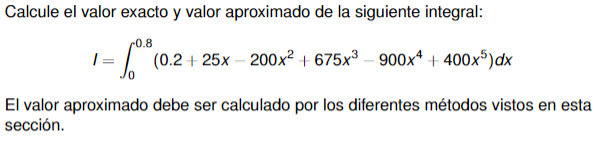

f = @(x) (0.2 + 25*x - 200*x.^2 + 675*x.^3 - 900*x.^4 + 400*x.^5)

f = function_handle with value:
    @(x)(0.2+25*x-200*x.^2+675*x.^3-900*x.^4+400*x.^5)


syms x
Exacto = int(f(x),0,0.8)

$$Exacto = \frac{3076}{1875}$$

a = 0;
b = 0.8;
n = 4;
h = (b-a)/n

h =    0.200000000000000


x = [a:h:b]

x =                    0   0.200000000000000   0.400000000000000   0.600000000000000   0.800000000000000


xpar=x(2:2:length(x)-1);
ximpar=x(3:2:length(x)-2);
Isimpcomp=(h/3)*(f(a)+4*sum(f(xpar))+2*sum(f(ximpar))+f(b))

Isimpcomp =    1.623466666666672


ErrorABS=vpa(abs(Exacto-Isimpcomp),4)

$$ErrorABS = 0.01707$$

ErrorREL = ErrorABS/abs(Exacto)

$$ErrorREL = 0.010403120936279738526667955105032$$